# Identificazione in presenza di limitazioni di velocità/posizione massima.

I sistemi meccanici sono spesso identificati in frequenza. 

In questo script vedremo l'identificazione con sweep in frequenza (chirp)

NOTA: aggiungere al path "labauto_control_library"

## Esempio

consideriamo il modello meccanico motore-trasmissione-carico, con trasmissione elastica e presenza di attrito statico.

Il sistema ha un ingresso (la coppia motore), e due uscite (posizione e velocità motore). Ci interessa trovare un modello lineare che approssima la relazione coppia-velocità.

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi

robot=ElasticRoboticSystem('progetto1');

Unable to resolve the name 'progetto1.inputToStateSimulation'.

Error in ElasticRoboticSystem (line 22)
            obj.inputToState=eval(sprintf('%s.inputToStateSimulation',model_name));

robot.show;
Tc = robot.getSamplingPeriod;
robot.initialize;

Utilizzo un [segnale chirp ](https://it.wikipedia.org/wiki/Chirp)per eccitare il range di frequenze $[\omega_0 \rightarrow \omega_1]$. La scelta del range dipende dagli obiettivi di controllo (quando è la mia $\omega_c$ desiderata) e di norma viene scelta in via iterativa.

t=(0:Tc:20)';

w0=10; %rad/s
w1=3000; %rad/s     Fs=1/Ts, Ws=2*pi/Ts, max w1 = 0.5*Ws=pi/Ts
control_action_identificazione = chirp(t,w0/2/pi,t(end),w1/2/pi, 'logarithmic');

La scelta dell'ampiezza deve essere fatta sequendo i criteri:

- abbastanza grande da eccitare il sistema

- abbastanza piccola da non andare a fine corsa o dannaggiare il sistema.

ampliezza_identificazione=20;

Scalo il segnale

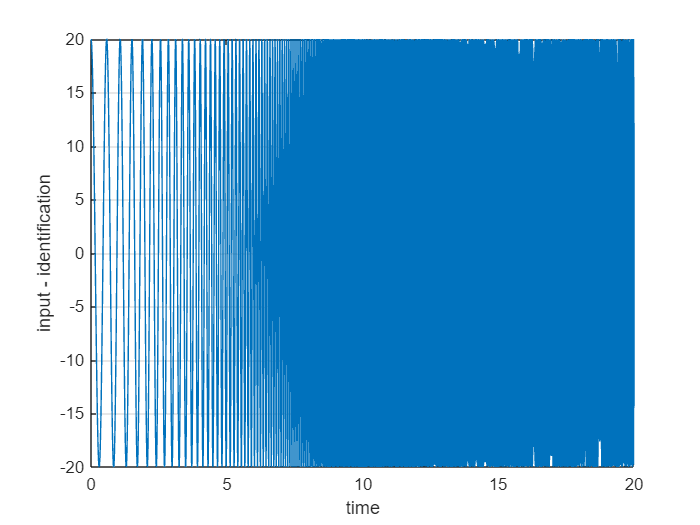

control_action=control_action_identificazione*ampliezza_identificazione;
figure
plot(t,control_action)
xlabel('time')
ylabel('input - identification')
grid on

Spettrogramma (contenuto frequenziale al variare del tempo)

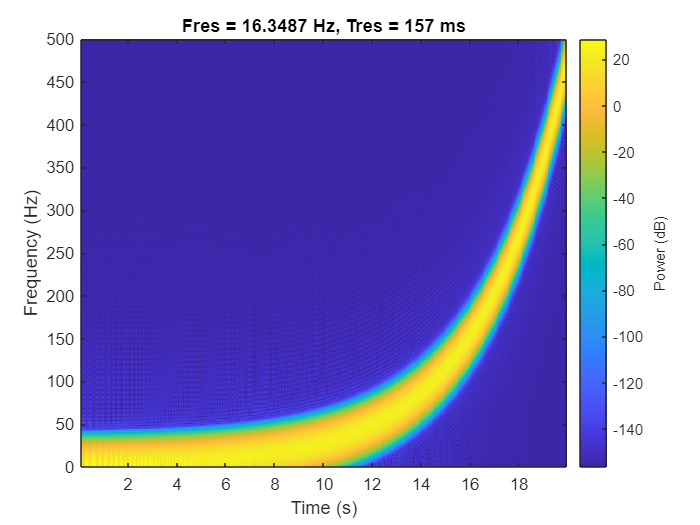

pspectrum(control_action,1/Tc,'spectrogram');

## Simulazione sistema

testo il sistema in anello aperto

aspetto 60 secondi in modo che il sistema "cada" prima di partire

joint_torque=0;
for idx=1:60e3
    % apply torque
    robot.writeActuatorValue(joint_torque);
    % simulate
    robot.simulate();
end

Index exceeds the number of array elements. Index must not exceed 1.

Error in MechanicalSystem/saturationControlAction (line 142)
                if (u(iu)>obj.umax(iu))

Error in MechanicalSystem/simulate (line 66)
            usat=obj.saturationControlAction(obj.u);

comincio l'identificazione

measured_output=zeros(length(t),robot.getOutputNumber);
for idx=1:length(t)
    measured_output(idx,:) = robot.readSensorValue();
    joint_torque = control_action(idx);
    % apply torque
    robot.writeActuatorValue(joint_torque);
    % simulate
    robot.simulate();
end

figure
subplot(2,1,1)
plot(t,measured_output(:,2))
xlabel('time')
ylabel('output - velocità motore')
grid on

subplot(2,1,2)
plot(t,control_action)
xlabel('time')
ylabel('input - coppia motore')
grid on

## Identificazione

### Calcolo risposta in frequenza

Definisco l'oggetto identification data (iddata)

identification=iddata(measured_output(:,2),control_action,Tc);

Calcolo la risposta in frequenza con il comando e la plotto

freq_resp_ident = spafdr(identification);

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
h=bodeplot(freq_resp_ident, bode_opts);
grid on
hold on

plotto l'intervallo di confidenza

showConfidence(h,3)

Plotto la frequenza di inizio del segnale eccitante


plot(w0*[1 1],ylim,'--r')
hold off

Nella parte a sinistra nella linea tratteggiata,il segnale non ha contribuito informatico apprezzabile ed è "disturbato" dalla presenza dell'attrito statico.

### Stima del modello

modello_continuo = ssest(freq_resp_ident,3);
modello_discreto = ssest(freq_resp_ident,3,'Ts',Tc);

### Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident, bode_opts);

si può aggiungere l'intervallo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

bode(modello_continuo,modello_discreto, bode_opts)

hold off
grid on
legend('Identification','Modello continuo','Modello discreto')

## Identificazione modello con peso sulle frequenza

Il modello si concentra molto sulla bassa frequenza e meno nella zona che ci interessa

Devo dire al modello di non considerare le basse frequenze. 

Creo un vettore di pesi da dare allo stimatore (peso basso, poca importanza).

Impongo la stima di un modello stabile. **Nota**: un pendolo inverso (o un robot antropomorfo messo sulla verticale) non sono stabili.

peso=ones(length(freq_resp_ident.Frequency),1);
wpeso0=100;
wpeso1=2000;
peso(freq_resp_ident.Frequency<wpeso0)=1e-5;
peso(freq_resp_ident.Frequency>wpeso1)=1e-5;

 
opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
modello_continuo2 = ssest(freq_resp_ident,3,opts);
modello_discreto2 = ssest(freq_resp_ident,3,'Ts',Tc,opts);

### Grafico modelli

aggiungo opzione per evitare la molteplicità di 360° nella base

figure
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

plotto i dati sperimentali

h=bodeplot(freq_resp_ident, bode_opts);

si può aggiungere l'intervallo di confidenza (in questo caso 3*sigma)

hold on
showConfidence(h,3)

grafico i modelli stimati

bode(modello_continuo2,modello_discreto2, bode_opts)
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')

hold off
grid on
xlim([1e-1 1e4])

legend('Identification','Modello continuo','Modello discreto')

Ricordiamoci di validare facendo un'altra identificazione con un segnale in ingresso.

- Prova di identificazione

- Identificazione del modello

- prova di validazione

- testare modello (trovato nel punto 2) con i dati di validazione